# Satelliete Attitude Control

Set dimensions and mass of satellite:

clear
% Make a rectangular prism:
lx = 1;
ly = 2;
lz = 5;

m = 50; %satellite mass

p.I_x = (1/12)*m*(ly^2+lz^2);
p.I_y = (1/12)*m*(lz^2+lx^2);
p.I_z = (1/12)*m*(lx^2+ly^2);

Set control gains:

K_p = 0.75;
K_d = 1;
K_i = 0.05;

There's a little complexity hiding here: technically there are at least three different control gains, one for each of the angles we're trying to set; plus more for cross terms (essentially there is a 3x3 gain matrix). But, in the code we just scale each of the controls for each of the angles by the moment of inertia for that axis so that each of the axis is being controlled similarly.

Note: Target orientation is set randomly; it is shown in the animation as the clear prism; block starts from rest with all angles at 0.

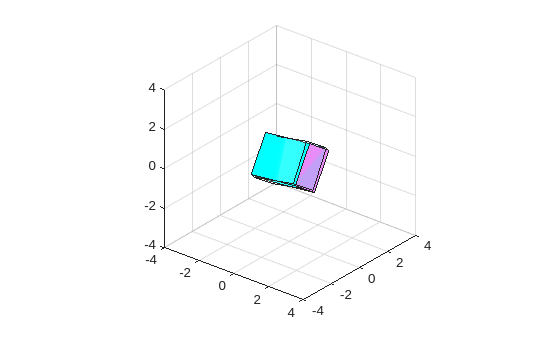

p.Kp = K_p*diag([p.I_x,p.I_y,p.I_z]); % proportional gain matrix
p.Kd = K_d*diag([p.I_x,p.I_y,p.I_z]); % derivative gain matrix
p.Ki = K_i*diag([p.I_x,p.I_y,p.I_z]); % integral gain matrix

% theta_x; theta_y; theta_z; omega_x; omega_y; omega_z
z0 = [0;0;0;0;0;0]; % initial euler angles and angular velocities
p.c = (pi/3)*rand(3,1); %target euler angles

tf = 10; %simulation duration

function z_dot = EOM(~,z,p)
z_dot = [(z(4)*cos(z(3)) - z(5)*sin(z(3)))*sec(z(2));
          z(4)*sin(z(3)) + z(5)*cos(z(3));
        -(z(4)*cos(z(3)) - z(5)*sin(z(3)))*tan(z(2)) + z(6);
         (p.I_y-p.I_z)*z(5)*z(6)/p.I_x;
         (p.I_z-p.I_x)*z(6)*z(4)/p.I_y;
         (p.I_x-p.I_y)*z(4)*z(5)/p.I_z; % free response
         p.c - z(1:3)]; % integrated error 

P = p.Kp*(p.c - z(1:3)); % proportional control
D = p.Kd*-z_dot(1:3);    % derivative control
I = p.Ki*z(7:9);         % integral control
z_dot = z_dot + [0;0;0;diag([1/p.I_x,1/p.I_y,1/p.I_z])*(P+D+I);0;0;0];
end

[t,z] = ode45(@(t,z) EOM(t,z,p),linspace(0,tf,20*tf),[z0;0;0;0]);
z = z';

% animate:
close all
figure(1)
w = quiver3(0,0,0,0,0,0);
prism = plotPrism(lx,ly,lz,[0,1,1],1);
final = plotPrism(lx,ly,lz,[1,1,1],0.2);
set(final,'Matrix',[spinmat(p.c(1),1)*spinmat(p.c(2),2)*spinmat(p.c(3),3),[0;0;0];[0,0,0,1]])

axis equal
view([38.96 27.90])
xlim([-1,1]*lz*0.8);ylim([-1,1]*lz*0.8);zlim([-1,1]*lz*0.8)

for i=1:length(t)
    mat = spinmat(z(1,i),1)*spinmat(z(2,i),2)*spinmat(z(3,i),3);
    set(prism,'Matrix',[mat,[0;0;0];[0,0,0,1]])
    set(w,'UData',mat(1,:)*z(4:6,i),'VData',mat(2,:)*z(4:6,i),'WData',mat(3,:)*z(4:6,i))
    drawnow
end

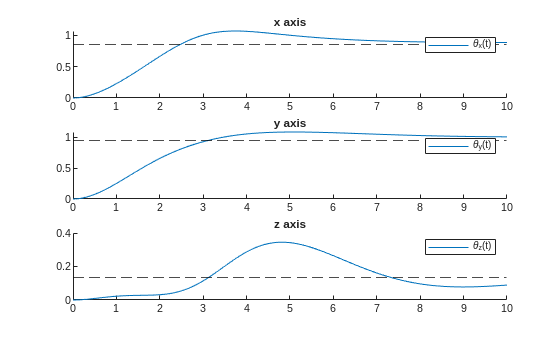

figure(2)
clf
subplot(3,1,1)
title('x axis')
hold on
plot(t,z(1,:),'DisplayName','\theta_x(t)')
legend('AutoUpdate','off')
yline(p.c(1),'--k')

subplot(3,1,2)
title('y axis')
hold on
plot(t,z(2,:),'DisplayName','\theta_y(t)')
legend('AutoUpdate','off')
yline(p.c(2),'--k')

subplot(3,1,3)
title('z axis')
hold on
plot(t,z(3,:),'DisplayName','\theta_z(t)')
legend('AutoUpdate','off')
yline(p.c(3),'--k')

function h = plotPrism(l1,l2,l3,colr,alpha)
h = hgtransform;
[a,b] = meshgrid([-1,1]/2, [-1,1]/2); c = ones(2)/2;
colr = repmat(reshape(colr,[1,1,3]),[2,2,1]);
surf( a*l1, b*l2, c*l3,rand(2,2,3),'FaceAlpha',alpha,'Parent',h)
surf( a*l1, b*l2,-c*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( c*l1, a*l2, b*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf(-c*l1, a*l2, b*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( b*l1, c*l2, a*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( b*l1,-c*l2, a*l3,colr,'FaceAlpha',alpha,'Parent',h)
end

function P_AB = spinmat(alpha, i)
% A compression and improvement of rotx, roty, and rotz functions
arguments
    alpha
    i (1,1) {mustBeInteger}
end

l = length(alpha);
if l>1
    alpha= reshape(alpha,[1 1 l]);
end

switch i
    case 1 %rotation about x-axis
        P_AB = [ones(1,1,l),zeros(1,2,l); zeros(2,1,l),[cos(alpha),-sin(alpha);sin(alpha),cos(alpha)]];
    case 2 %rotation about y-axis
        P_AB = [cos(alpha),zeros(1,1,l),sin(alpha);zeros(1,1,l),ones(1,1,l),zeros(1,1,l);-sin(alpha),zeros(1,1,l),cos(alpha)];
    case 3 %rotation about z_axis
        P_AB = [[cos(alpha),-sin(alpha);sin(alpha),cos(alpha)],zeros(2,1,l);zeros(1,2,l),ones(1,1,l)];
end
end